================================================================================

# Práctica 2 - Algoritmos

## Aritmética de punto/coma flotante en MATLAB

Lectura recomendada: [Floating Points: IEEE Standard Unifies Arithmetic Model](https://es.mathworks.com/company/newsletters/articles/floating-points-ieee-standard-unifies-arithmetic-model.html?s_tid=answers_rc2-3_p6_Topic)

Lecturas complementarias: 

- [Floating Point Arithmetic Before IEEE 754](https://blogs.mathworks.com/cleve/2019/01/18/floating-point-arithmetic-before-ieee-754/)

- [A Glimpse into Floating-Point Accuracy](https://blogs.mathworks.com/loren/2006/08/23/a-glimpse-into-floating-point-accuracy/?s_tid=srchtitle)

- [Floating Point Numbers](https://es.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html)

[Toby Driscoll (2021). IEEE 754 binary representation](https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation) (función al final del documento), MATLAB Central File Exchange. 

El formato de memoria de un valor de punto flotante de doble precisión IEEE 754: Ilustrado en forma de byte, los bits del exponente y la fracción están distribuidos como:

[0][0000000 0000][0000 00000000 00000000 00000000 00000000 00000000 00000000]

En notación decimal, un número $x$ es igual a:

`     fl(x) = (-1)^S * (1 + M/(2^52)) *  2^(E-1023),`

excepto para valores especiales 0, Inf, NaN y números denormalizados (entre 0 y REALMIN). 

suma = 2^5

suma = 32

[S,E,M] = ieee754(suma)

S = '0'

E = '10000000100'

M = '0000000000000000000000000000000000000000000000000000'

[S,E,M] = ieee754(suma,'dec')

S = 0

E = 1028

M = 0

**Ejemplo 1.** "Catastrophic Cancellation"

La cancelación catastrófica es el fenómeno por el cual restar buenas aproximaciones a dos números cercanos puede producir una muy mala aproximación a la diferencia de los números originales.

sqrt(1e-16 + 1) - 1

ans = 0

**Ejemplo 2. **Ruido numérico

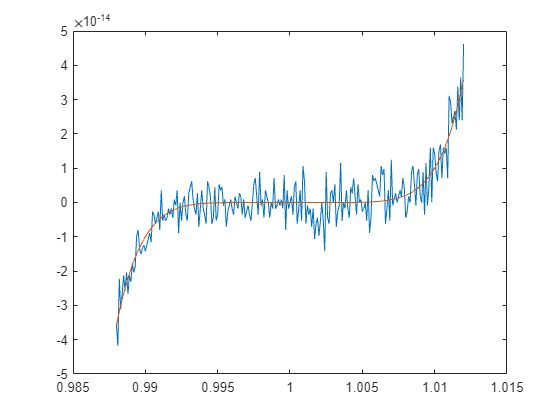

x = 0.988:.0001:1.012;
y = x.^ 7- 7* x.^ 6+ 21* x.^ 5- 35* x.^ 4+ 35* x.^ 3 - 21* x.^ 2+ 7* x- 1;
z = (x-1).^7;
plot( x, y, x, z)

## Ejercicios

### Evitando problemas comunes con la aritmética de coma flotante

#### **Ejercicio 1. **Redondeo o lo que obtiene no es lo que se espera

- El número $a=4/3$ no tiene mantisa binaria exacta, ya que todo número binario en coma flotante tiene una representación decimal exacta. Sea $b=a-1$, calcular E (exponente) y M (mantisa) de la representación binaria en doble precisión de $b$, $2b$, y $3b$. ¿Por qué es esa la mantisa de $3b$? Comprobar que $c=3b$ no es igual a $1$. ¿Cuál es el error relativo? Compararlo con el épsilon de la máquina (eps en Matlab).

        *(Si se quieren ver las representaciones en binario puro se puede usar la función num2bin().BiCimal que está al final del documento.)*

%bias = 1023;
a = 4/3;
b = a - 1;
b2 = 2*b;
b3 = 3*b;
b3 == 1

ans = logical
   0


[Sb,Eb,Mb] = ieee754(b, 'dec')

Sb = 0

Eb = 1021

Mb = 1.5012e+15

[S2b,E2b,M2b] = ieee754(2*b, 'dec')

S2b = 0

E2b = 1022

M2b = 1.5012e+15

[S3b,E3b,M3b] = ieee754(3*b, 'dec')

S3b = 0

E3b = 1022

M3b = 4.5036e+15

c = (-1)^S3b * (1 + M3b/(2^52)) *  2^(E3b-1023);
c == 1

ans = logical
   0


Er = abs(1 - c) / 1;   %% La división entre 1 sobra, pero para ser fiel a la fórmula del Er lo pongo
Er == eps

ans = logical
   1


Se puede observar que el error relativo es igual al épsilon de la máquina

- Verificar que 0.1 no tiene representación binaria exacta. ¿MATLAB trunca o redondea la mantisa? Comprueba que sumar diez veces 0.1 no es igual a 1. Explicar qué está sucediendo.

[SZ,EZ,MZ] = ieee754(0.1, 'dec')

SZ = 0

EZ = 1019

MZ = 2.7022e+15

MatLab ha redondeado la mantissa

zeroUn = (-1)^SZ * (1 + MZ/(2^52)) *  2^(EZ-1023);
zeroUn == 0.1

ans = logical
   1


a = 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1

a = 1.0000

a == 1

ans = logical
   0


Al tener un error tan minúsculo en cada 0.1 (porque no se puede representar exactamente), aunque MatLab diga que a = 1.000, cuando se compara realmente con 1 no es verdad.

- Hay "gaps" entre los números en coma flotante: comprobar y argumentar que Matlab no distingue entre $2^{53}$ y $2^{53}+1$.

2^53 == 2^53 + 1

ans = logical
   1


Claramente, MatLab ha dicho que dos cantidades diferentes son iguales.

[St1, Et1, Mt1] = ieee754(2^53)

St1 = '0'

Et1 = '10000110100'

Mt1 = '0000000000000000000000000000000000000000000000000000'

[St2, Et2, Mt2] = ieee754(2^53 + 1)

St2 = '0'

Et2 = '10000110100'

Mt2 = '0000000000000000000000000000000000000000000000000000'

Como se puede ver, en coma flotante los dos números se representan igual.

- Comprobar que el seno de $\pi$ no es cero.

sin(pi) == 0

ans = logical
   0


[Sp, Ep, Mp] = ieee754(sin(pi))

Sp = '0'

Ep = '01111001010'

Mp = '0001101001100010011000110011000101000101110000000111'

Ea = abs(0 - sin(pi))

Ea = 1.2246e-16

#### **Ejercicio 2. **El orden de las operaciones puede hacer variar el resultado del cálculo

- Comprobar y argumentar que `1e-16 +1 - 1e-16` y `1e-16 - 1e-16 + 1` no dan el mismo resultado en MATLAB. ¿Cuál es correcto?

c1 = 1e-16 +1 - 1e-16

c1 = 1.0000

c2 = 1e-16 - 1e-16 + 1

c2 = 1

c1 == c2

ans = logical
   0


[S, E, M] = ieee754(c1)

S = '0'

E = '01111111110'

M = '1111111111111111111111111111111111111111111111111111'

[S, E, M] = ieee754(c2)

S = '0'

E = '01111111111'

M = '0000000000000000000000000000000000000000000000000000'

Se puede ver que el resultado correcto es el de c2, ya que la mantissa es 0 y el exponente 1023-1023, así que el cálculo es 1.0 * 2^0, en lugar de 1.0000algo *2^1, que no es exactamente 1.

- Comprobar y argumentar que `0.3 - 0.1 - 0.2 == -0.1 - 0.2 + 0.3 `es falso en MATLAB.

q1 = 0.3 - 0.1 - 0.2

q1 = -2.7756e-17

q2 = -0.1 - 0.2 + 0.3

q2 = -5.5511e-17

q1 == q2

ans = logical
   0


[Sz3, Ez3, Mz3] = ieee754(0.3)

Sz3 = '0'

Ez3 = '01111111101'

Mz3 = '0011001100110011001100110011001100110011001100110011'

[Sz2, Ez2, Mz2] = ieee754(0.2)

Sz2 = '0'

Ez2 = '01111111100'

Mz2 = '1001100110011001100110011001100110011001100110011010'

[Sz1, Ez1, Mz1] = ieee754(0.1)

Sz1 = '0'

Ez1 = '01111111011'

Mz1 = '1001100110011001100110011001100110011001100110011010'

Al hacer una operación con números no representables en coma flotante, se pierde la exactitud ya que se fuerza un redondeo, por tanto, si primero se hace 0.3 - 0.1, dará un resultado que al operar con 0.2 no será correcto. De la misma forma si primero se hace -0.1 - 0.2, el resultado no es -0.3, así que al operarlo con el mismo no da un resultado correcto. Ninguna de las dos operaciones dan ni el mismo resultado ni el que sería correcto.

#### Ejercicio 3. Épsilon de la máquina

Determinar el épsilon de la máquina. Para ello, calcular $1 + x$ con $x = 2^{-i}$ para $i = 1, 2, \ldots$ mientras para MATLAB sea mayor a 1. Comparar con el $\texttt{eps}$ de MATLAB. 

i = 1;
results = [];
format long
while 1+(2^-i) > 1
    results(end+1) = [1+2^(-i)];
    i = i+1;
end
table(results')

ans = 52×1 table
          Var1      
    ________________

                 1.5
                1.25
               1.125
              1.0625
             1.03125
            1.015625
           1.0078125
          1.00390625
         1.001953125
        1.0009765625
       1.00048828125
      1.000244140625
     1.0001220703125
    1.00006103515625
    1.00003051757812
    1.00001525878906


eps == 2^-(i-1)     %% Al salir del bucle, i = 53, que ya no cumple la condición

ans = logical
   1


Calcular los valores de $1 + \epsilon$ y $1 - \epsilon$. ¿Qué se observa? Argumentar el resultado.

peps = 1-eps

peps =    1.000000000000000


meps = 1+eps

meps =    1.000000000000000


peps == meps

ans = logical
   0


[Speps, Epeps, Mpeps] = ieee754(peps)

Speps = '0'

Epeps = '01111111110'

Mpeps = '1111111111111111111111111111111111111111111111111110'

[Smeps, Emeps, Mmeps] = ieee754(meps)

Smeps = '0'

Emeps = '01111111111'

Mmeps = '0000000000000000000000000000000000000000000000000001'

meps y peps son números diferentes ya que son reconocibles por la máquina, si se le sumase y restase un número más pequeño que el épsilon de la máquina, no se llegaría a ver la diferencia.

En la representación de coma flotante, se observa que la diferencia entre los dos números es (obviamente) el bit de menos peso del exponente y la inversa de los bits de la mantissa.

#### **Ejercicio 4. Realmax**

Hallar las potencias sucesivas de $10$ con exponente desde $1$ hasta que el valor de $10^{k}$ sea "infinito" para un exponente $k$ y comprobar que entonces $\frac{1}{10^k}$ da 0. Comparar $10^k$ con realmax en doble precisión IEEE 754.

pots = [];
k = 1;
while 10^k ~= Inf
    pots(end+1) = 10^k;
    k = k+1;
end
table(pots')

ans = 308×1 table
         Var1      
    _______________

                 10
                100
               1000
              10000
             100000
            1000000
           10000000
          100000000
         1000000000
        10000000000
       100000000000
      1000000000000
     10000000000000
    100000000000000
              1e+15
              1e+16


0 == 1/10^k         %% Ciertamente 1/10^309 es infinito

ans = logical
   1


trueInfinito = realmax

trueInfinito =     1.797693134862316e+308


trueInfinito == 10^k

ans = logical
   0


#### Ejercicio 5. Números denormales

Calcular iterativamente la potencia de dos más pequeña distinta a cero en MATLAB. Compararla con realmin en doble precisión IEEE 754 y con eps*realmin. 

              Nota: la mayoría de los ordenadores permiten números denormales excepcionales entre realmin y eps*realmin (ver [Floating Points: IEEE Standard Unifies Arithmetic Model](https://es.mathworks.com/company/newsletters/articles/floating-points-ieee-standard-unifies-arithmetic-model.html?s_tid=answers_rc2-3_p6_Topic)).

minuspots = [];
k = 1;
while 2^-k ~= 0
    minuspots(end+1) = 2^-k;
    k = k+1;
end
table(minuspots')

ans = 1074×1 table
          Var1       
    _________________

                  0.5
                 0.25
                0.125
               0.0625
              0.03125
             0.015625
            0.0078125
           0.00390625
          0.001953125
         0.0009765625
        0.00048828125
       0.000244140625
      0.0001220703125
      6.103515625e-05
     3.0517578125e-05
    1.52587890625e-05


trueMinimum = realmin

trueMinimum =     2.225073858507201e-308


trueMinimum == 2^-(k-1)

ans = logical
   0


eps*realmin == 2^-(k-1)

ans = logical
   1


a =     4.940656458412465e-324


#### Ejercicio 6. Propagación del error. Estabilidad numérica.

Para calcular las integrales     $$\displaystyle I_{n}=\int_{0}^{1} x^n e^{x-1}dx\,,\quad n\ge~1\,,$$ disponemos de dos métodos iterativos diferentes:

a)  $I_{n}=1-nI_{n-1}\,,\quad  n\ge 2,\quad I_{1}=1/e.$

b)  $I_{n-1}=\frac{1-I_n}{n}\,,\quad  n\ge 2,\quad I_{50}=0.$

Discute la estabilidad de las recurrencias.

#### Ejercicio 7. Propagación del error. Sistema lineal mal condicionado.

Resuelve el sistema $\left\{\begin{array}{rcrcr}2x&-&4y&=&1 \\ -2.998x&+&6.001y&=&2 \\\end{array}\right.$  utilizando la instrucción linsolve de MATLAB.

Compara la solución con la del sistema$\left\{\begin{array}{rcrcr}2x&-&4y&=&1 \\ -2.998x&+&6y&=&2 \\\end{array}\right.$. 

¿Cómo son las dos soluciones? ¿Es un problema estable? 

Calcula el número de condición de la matriz asociada al sistema lineal (funciones cond, rcond).

%Internal 

function [s,e,f] = ieee754(x,fmt)
    % Copyright 2009 by Toby Driscoll (driscoll@udel.edu). 
    % Thanks to Andreas Luettgens for the suggestion of NUM2HEX.
    
    if ~isreal(x) || numel(x) > 1 || ~isa(x,'double')
        error('Real, scalar, double input required.')
    end
    hex = num2hex(x);        % string of 16 hex digits for x
    dec = hex2dec(hex');     % decimal for each digit (1 per row)
    bin = dec2bin(dec,4);    % 4 binary digits per row
    bitstr = reshape(bin',[1 64]);  % string of 64 bits in order
    
    % Return options
    if nargout<2
        s = bitstr;      
    else
        s = bitstr(1);
        e = bitstr(2:12);
        f = bitstr(13:64);
        if nargin > 1 && isequal(lower(fmt),'dec')
            s = bin2dec(s);  e = bin2dec(e);  f = bin2dec(f);
        end
    end 
end

function B = num2bin(X)
%   % Unpacks the real number X into a binary form, splitting it into a struct
  % usage: B = num2bin(X)
  %
  % arguments: (input) 
  %  X - scalar, typically double precision (real) but also all
  %      standard numeric formats are supported for conversion, thus:
  %
  %      double, single, uint8, uint16, uint32, uint64,
  %      logical, int8, int16, int32, int64
  %
  %      complex input will currently generate an error. You can always
  %      call num2bin on both the real and imaginary parts of the number.
  %
  % arguments: (output)
  %  B - a struct, containing fields that break X down into a binary
  %      mantissa, exponent in terms of powers of 2, and a sign.
  %
  %        B.Class = The numeric class of the number X.
  %        B.Sign = +1, 0, or -1. If X==0, then B.Sign will be 0.
  %        B.Mantissa = Binary mantissa as a string of bits. No
  %          "decimal" point is included.
  %        B.Exponent = Power of 2 to be applied to the mantissa.
  %        B.BinaryExpansion = We can write any floating point
  %          number as a sum of explicit powers of 2. I.e, ignoring
  %          the sign of X, for 5.125, we would see a list of the
  %          powers of 2 that would generate X, thus [2 0 -3],
  %          since 5.125 = 2^2 + 2^0 + 2^-3.
  %        B.BiSci = A binary version of scientific notation, so the
  %          binary mantissa bits of B, with then a power of 2 appended
  %          at the end. That is, for -0.1, we would see
  %            '-1.100110011001100110011001100110011001100110011001101 B-4'
  %          The 'B-4' at the end representing 2^-4.
  %        B.BiCimal = A binary "decimal" form, with no exponent.
  %          For X = -0.123,, we would expect:
  %            '-0.0001111101111100111011011001000101101000011100101011'
  %
  % Author: John D'Errico
  
  if nargin ~= 1
    error('Only one argument may be supplied')
  end
  
  % ensure that X is scalar
  if numel(X) ~= 1
    error('NUM2BIN requires scalar input.')
  end
  
  if ~isreal(X)
    error('NUM2BIN applies only to a real number or an integer form.')
  end
  
  B.Class = class(X);
  switch B.Class
    case 'logical'
      % single bits
      B.Sign = sign(X);
      B.Exponent = 0;
      B.Mantissa = char('0' + X);
      B.BinaryExpansion = find(B.Mantissa == '1') - 1;
      if X
        B.BiSci = '1.B0';
        B.BiCimal = '1';
      else
        B.BiSci = '0';
        B.BiCimal = '0';
      end
    
    case {'uint8', 'uint16', 'uint32', 'uint64'}
      % 8, 16, 32, 64 bits, no sign
      % use dec2bin if X is no larger than 2^53-1
      
      % the sign can be -1, 0 or 1. for unsigned integers, -1 is rare. ;)
      B.Sign = sign(X);
      
      % Note: easier to use dec2bin than to extract the hex
      % representation and convert that.
      if X <= 9007199254740991
        % we can safely use dec2bin
        B.Mantissa = dec2bin(X);
      else
        % as an unsigned integer, X can only exceed that
        % value only if it is uint64. dec2bin will fail here.
        two32 = uint64(2^32);
        B.Mantissa = dec2bin(rem(X,two32),32);
        X = X/two32; % will truncate here, so stripping off the low part.
        B.Mantissa = [dec2bin(X),B.Mantissa];
      end
      
      % The exponent is just 1 less than the number of bits found
      % in the mantissa.
      B.Exponent = numel(B.Mantissa) - 1;
      
      B.BinaryExpansion = B.Exponent - find(B.Mantissa == '1') + 1;
      
      if X
        B.BiSci = [B.Mantissa(1),'.',B.Mantissa(2:end),' B',num2str(B.Exponent)];
        B.BiCimal = B.Mantissa;
      else
        B.BiSci = '0';
        B.BiCimal = '0';
      end
      
    case {'int8', 'int16', 'int32', 'int64'}
      % it is still an integer, but watch out for negatives
      B.Sign = sign(X);
      
      % discard the sign now
      X = abs(X);
      
      % Note: easier to use dec2bin than to extract the hex
      % representation and convert that.
      if X <= 9007199254740991
        % we can safely use dec2bin
        B.Mantissa = dec2bin(X);
      else
        % as a signed integer, X can only exceed that
        % magnitude only if it is int64. dec2bin will fail here.
        two32 = int64(2^32);
        B.Mantissa = dec2bin(rem(X,two32),32);
        X = X/two32; % will truncate here, so strip off the low part.
        B.Mantissa = [dec2bin(X),B.Mantissa];
      end
      
      % The exponent is just 1 less than the number of bits found
      % in the mantissa.
      B.Exponent = numel(B.Mantissa) - 1;
 
      B.BinaryExpansion = B.Exponent - find(B.Mantissa == '1') + 1;
      
      % if X just tests for non-zero X.
      if X
        B.BiSci = [B.Mantissa(1),'.',B.Mantissa(2:end),' B',num2str(B.Exponent)];
        B.BiCimal = B.Mantissa;
        if B.Sign < 0
          B.BiSci = ['-',B.BiSci];
          B.BiCimal = ['-',B.BiCimal];
        end
      else
        B.BiSci = '0';
        B.BiCimal = '0';
      end
      
    case 'double'
      % a floating point double gets converted first to hex,
      % then to binary. Then we extract the sign, the mantissa,
      % and the exponent separately.
      
      if isnan(X)
        B.Sign = NaN;
        B.Exponent = NaN;
        B.Mantissa = '1000000000000000000000000000000000000000000000000000';
        B.BinaryExpansion = 'NaN';
        B.BiSci = 'NaN';
        B.BiCimal = 'NaN';
        return
      end
      
      % convert a double precision number to an exact hex form
      hex = num2hex(X);
      
      % now a table lookup will convert each hex digit into binary
      tablout = dec2bin(0:15);
      tablin = transpose('0123456789abcdef');
      
      % ismember does the work here
      [~,hexind] = ismember(hex,tablin);
      
      Xbin = tablout(hexind,:);
      Xbin = reshape(Xbin',64,[])';
      
      % So the sign bit is bit number 1. 1 --> X < 0
      % Simpler to just use the sign function though.
      % bits 13-64 are the mantissa.
      % bits 2-12 are the exponent
      B.Sign = sign(X);
      
      expon = Xbin(:,2:12);
      mant = Xbin(:,13:64);
      
      % convert the exponent to an integer power of 2
      % it will tell us how by many bits to shift our mantissa
      % to the right or left
      if X==0
        % when X was zero, there is no need to shift anything
        B.Exponent = 0;
      else
        B.Exponent = bin2dec(expon) - 1023;
      end
      
      % The mantissa is a number expressed in binary,
      % we could think of it in the form
      %
      %   N = Sign*(1+Mantissa*2^(-52))*(2^Expon2)
      % or,
      %   N = Sign*(2^52+Mantissa)*(2^(Expon2 - 52))
      % 
      % so essentially, the highest order non-zero bit was not stored at
      % all. As long as N was non-zero, there must be some non-zero bit.
      % 
      % However, all of that is pertinent only as long as X is not a
      % denormal/subnormal number. This case happens when the exponent is
      % the smallest possible (i.e., -1023), in which case, we do not
      % append a leading unit bit to the number, but a leading ZERO
      % bit instead.
      
      % set a flag for a denormal
      isdenormal = B.Exponent == -1023;

      if ~isdenormal
        B.Mantissa = ['1',mant];
      else
        % do not pre-pad with an implicit 1 for a denormal.
        B.Mantissa = ['0',mant];
      end
      
      B.BinaryExpansion = 1-find(B.Mantissa == '1') + B.Exponent;
      % in the case of a denormal, the exponent list needs to be shifted
      % by 1.
      B.BinaryExpansion = B.BinaryExpansion + isdenormal;
            
      % so now we have a 53 bit mantissa, with an implicit "bicimal"
      % point after the first bit. We need to insert/shift the
      % decimal point, at a location indicated by the exponent.
      % That may mean inserting the decimal to the right or to the left,
      % or it may mean padding zero bits on either side of the bit string.
      if X
        B.BiSci = [B.Mantissa(1),'.',B.Mantissa(2:end),' B',num2str(B.Exponent + isdenormal)];
        
        if B.Exponent == 0
          B.BiCimal = [B.Mantissa(1),'.',B.Mantissa(2:end)];
        elseif B.Exponent == -1
          B.BiCimal = ['0.',B.Mantissa];
        elseif B.Exponent < -1
          B.BiCimal = ['0.',repmat('0',1,abs(B.Exponent + isdenormal)-1),B.Mantissa];
        elseif B.Exponent > 52
          B.BiCimal = [B.Mantissa,repmat('0',1,B.Exponent - 52)];
        else
          % B.Exponent must be > 0, but does not exeed 52
          exploc = B.Exponent + 1;
          B.BiCimal = [B.Mantissa(1:exploc),'.',B.Mantissa(exploc+1:end)];
        end
        if B.Sign < 0
          B.BiSci = ['-',B.BiSci];
          B.BiCimal = ['-',B.BiCimal];
        end
      else
        B.BiSci = '0';
        B.BiCimal = '0';
      end
      
    case 'single'
      % a floating point single gets converted first to hex,
      % then to binary. Then we extract the sign, the mantissa,
      % and the exponent separately.
      
      if isnan(X)
        B.Sign = NaN;
        B.Exponent = NaN;
        B.Mantissa = '10000000000000000000000';
        B.BinaryExpansion = 'NaN';
        B.BiSci = 'NaN';
        B.BiCimal = 'NaN';
        return
      end
      
      % convert a double precision number to an exact hex form
      hex = num2hex(X);
      
      % now a table lookup will convert each hex digit into binary
      tablout = dec2bin(0:15);
      tablin = transpose('0123456789abcdef');
      
      % ismember does the work here
      [~,hexind] = ismember(hex,tablin);
      
      Xbin = tablout(hexind,:);
      Xbin = reshape(Xbin',32,[])';
      
      % So the sign bit is bit number 1. 
      % bits 10-32 are the mantissa.
      % bits 2-9 are the exponent
      B.Sign = sign(X);
      expon = Xbin(:,2:9);
      mant = Xbin(:,10:32);
      
      % convert the exponent to an integer power of 2
      % it will tell us how by many bits to shift our mantissa
      % to the right or left
      if X==0
        % when X was zero, there is no need to shift anything
        B.Exponent = 0;
      else
        B.Exponent = bin2dec(expon) - 127;
      end
      
      % set a flag for a denormal
      isdenormal = B.Exponent == -127;

      if ~isdenormal
        B.Mantissa = ['1',mant];
      else
        % do not pre-pad with an implicit 1 for a denormal.
        B.Mantissa = ['0',mant];
      end
      
      B.BinaryExpansion = 1-find(B.Mantissa == '1') + B.Exponent;

      % in the case of a denormal, the exponent list needs to be shifted
      % by 1.
      B.BinaryExpansion = B.BinaryExpansion + isdenormal;
      
      if X
        B.BiSci = [B.Mantissa(1),'.',B.Mantissa(2:end),' B',num2str(B.Exponent + isdenormal)];
         
        if B.Exponent == 0
          B.BiCimal = [B.Mantissa(1),'.',B.Mantissa(2:end)];
        elseif B.Exponent == -1
          B.BiCimal = ['0.',B.Mantissa];
        elseif B.Exponent < -1
          B.BiCimal = ['0.',repmat('0',1,abs(B.Exponent + isdenormal)-1),B.Mantissa];
        elseif B.Exponent > 22
          B.BiCimal = [B.Mantissa,repmat('0',1,B.Exponent - 22)];
        else
          % B.Exponent must be > 0, but does not exeed 22
          exploc = B.Exponent + 1;
          B.BiCimal = [B.Mantissa(1:exploc),'.',B.Mantissa(exploc+1:end)];
        end
        
        if B.Sign < 0
          B.BiSci = ['-',B.BiSci];
          B.BiCimal = ['-',B.BiCimal];
        end
        
      else
        B.BiSci = '0';
        B.BiCimal = '0';
      end
      
    otherwise
      error(['X is of class ',C,', which is not a supported class for conversion to binary'])
  end
  end

`Documento preparado por I. Parada el 21 de febrero de 2024`